% m = 100;
% c = 400;
% k = 40000;
% w = 2*(pi/180);
% f = 4000; % F
% x0 = 0; % 초기변위
% x_0 = 0.1; % 초기속도
% 
% 
% w_n = sqrt(k/m);
% f_0 = f/m;
% v_0wn = x0/w_n;


% syms z wn w f0
% A = [wn^2-w^2 2*z*wn*w; -2*z*wn*w wn^2-w^2];
% x = [f0; 0];
% An = inv(A)*x;
% 과제 6번 
r = linspace(0,2,500);
ze = [0.20; 0.25; 0.50; 0.70]; % zeta
% X = sqrt(((2*ze*r).^2+1)./((ones(size(ze))*(1-r.*r)+(2*ze*r).^2)));
G = 1./sqrt((1-r.^2).^2 + (2.*ze.*r).^2);
figure(1)
plot(r,G,'Linestyle','-','Linestyle','--','Linestyle',':','Linestyle','-.')
hold on
xline(1,'LineStyle','--','Label','\omega_n = \omega')

ans =   ConstantLine (\omega_n = \omega) with properties:

    InterceptAxis: 'x'
            Value: 1
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: '\omega_n = \omega'
      DisplayName: ''

  Show all properties


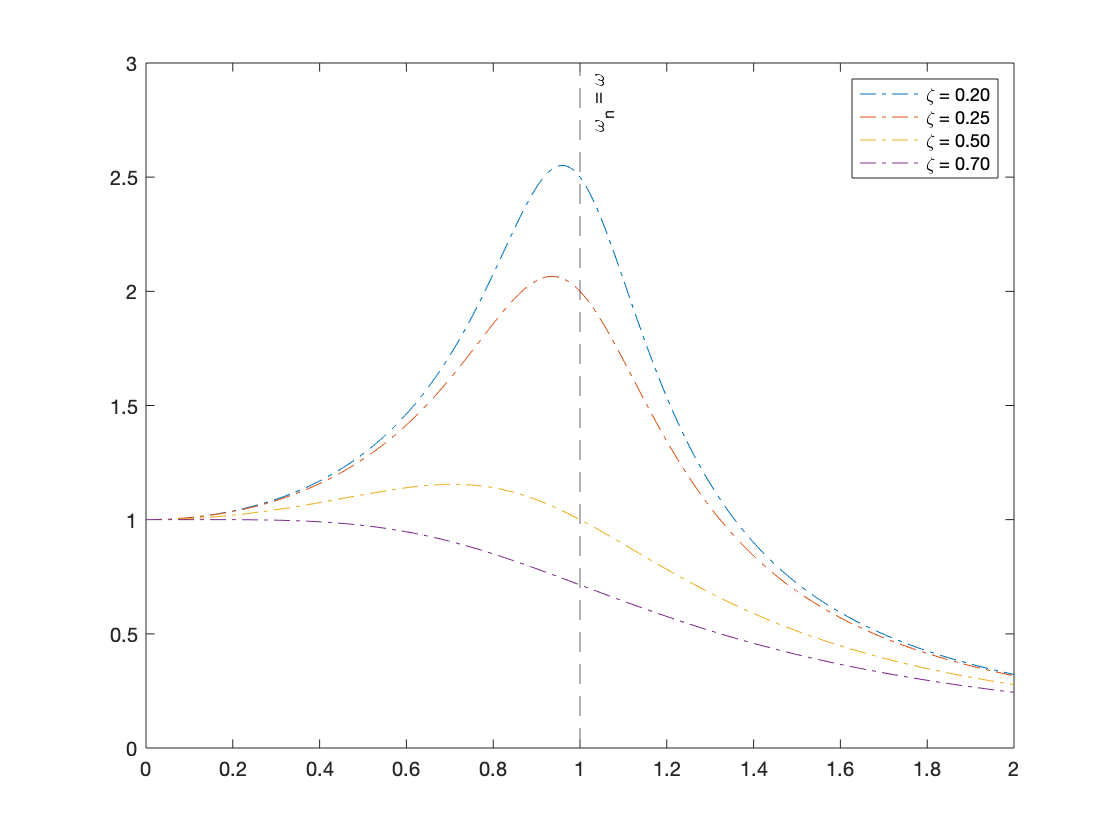


legend('\zeta = 0.20','\zeta = 0.25','\zeta = 0.50','\zeta = 0.70')